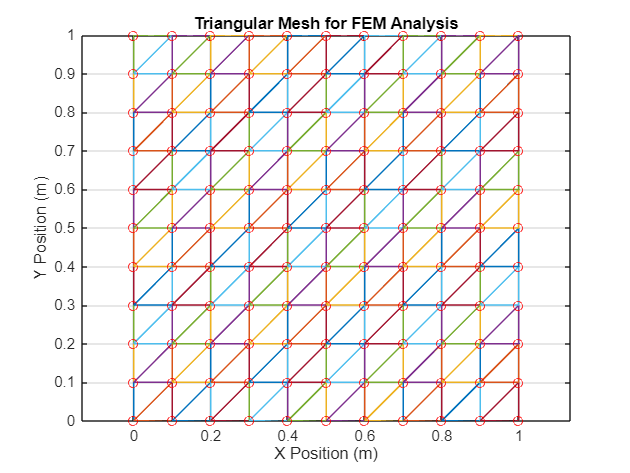

% Parameters
k = 50;              % Thermal conductivity (W/m.K)
Q = 1000;            % Heat source (W/m^2)
T_fixed = 25;        % Boundary temperature (°C)
Nx = 10;             % Elements along x
Ny = 10;             % Elements along y

% Generate structured grid
L = 1;
dx = L / Nx;
dy = L / Ny;
[x_grid, y_grid] = meshgrid(0:dx:L, 0:dy:L);
nodes = [x_grid(:), y_grid(:)];
n_nodes = size(nodes,1);

% Create triangular elements
elements = [];
for j = 1:Ny
    for i = 1:Nx
        n1 = i + (j-1)*(Nx+1);
        n2 = n1 + 1;
        n3 = n1 + (Nx+1);
        n4 = n3 + 1;

        % Triangle 1: lower-left to upper-right
        elements = [elements;
                    n1 n2 n4;
                    n1 n4 n3];m
    end
end


%% Plot the mesh
figure;
trimesh(elements, nodes(:,1), nodes(:,2), 'LineWidth', 1);
title('Triangular Mesh for FEM Analysis');
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis equal;
grid on;

%% Add annotations (optional)
hold on;
plot(nodes(:,1), nodes(:,2), 'ro', 'MarkerSize', 6); % Show nodes as red circles


% Print mesh statistics
fprintf('Mesh details:\n');

Mesh details:


fprintf('Number of nodes: %d\n', n_nodes);

Number of nodes: 121


fprintf('Number of elements: %d\n', size(elements,1));

Number of elements: 200



n_elements = size(elements,1);

% Initialize global matrices
K = zeros(n_nodes);
F = zeros(n_nodes,1);

% Assemble global stiffness matrix
for e = 1:n_elements
    idx = elements(e,:);
    coords = nodes(idx,:);
    x = coords(:,1); y = coords(:,2);
    
    A = polyarea(x, y);
    b = [y(2)-y(3); y(3)-y(1); y(1)-y(2)];
    c = [x(3)-x(2); x(1)-x(3); x(2)-x(1)];
    
    ke = (k / (4*A)) * (b*b' + c*c');
    K(idx, idx) = K(idx, idx) + ke;
end

% Apply heat source at center node
center_coord = [0.5, 0.5];
[~, center_node] = min(vecnorm(nodes - center_coord, 2, 2));
F(center_node) = Q;

% Apply Dirichlet BC: bottom edge (y=0)
tol = 1e-6;
fixed_nodes = find(abs(nodes(:,2)) < tol);
T = zeros(n_nodes, 1);
T(fixed_nodes) = T_fixed;
free_nodes = setdiff(1:n_nodes, fixed_nodes);

% Modify system
F_mod = F(free_nodes) - K(free_nodes, fixed_nodes) * T(fixed_nodes);
K_mod = K(free_nodes, free_nodes);

% Solve
T(free_nodes) = K_mod \ F_mod;

%% Display results
disp('Nodal Temperatures:');

Nodal Temperatures:


for i = 1:n_nodes
    fprintf('Node %d (%0.1f, %0.1f): T = %.2f°C\n', i, nodes(i,1), nodes(i,2), T(i));
end

Node 1 (0.0, 0.0): T = 25.00°C
Node 2 (0.0, 0.1): T = 26.82°C
Node 3 (0.0, 0.2): T = 28.59°C
Node 4 (0.0, 0.3): T = 30.23°C
Node 5 (0.0, 0.4): T = 31.67°C
Node 6 (0.0, 0.5): T = 32.82°C
Node 7 (0.0, 0.6): T = 33.65°C
Node 8 (0.0, 0.7): T = 34.19°C
Node 9 (0.0, 0.8): T = 34.50°C
Node 10 (0.0, 0.9): T = 34.67°C
Node 11 (0.0, 1.0): T = 34.72°C
Node 12 (0.1, 0.0): T = 25.00°C
Node 13 (0.1, 0.1): T = 26.85°C
Node 14 (0.1, 0.2): T = 28.65°C
Node 15 (0.1, 0.3): T = 30.33°C
Node 16 (0.1, 0.4): T = 31.81°C
Node 17 (0.1, 0.5): T = 32.99°C
Node 18 (0.1, 0.6): T = 33.79°C
Node 19 (0.1, 0.7): T = 34.30°C
Node 20 (0.1, 0.8): T = 34.58°C
Node 21 (0.1, 0.9): T = 34.72°C
Node 22 (0.1, 1.0): T = 34.77°C
Node 23 (0.2, 0.0): T = 25.00°C
Node 24 (0.2, 0.1): T = 26.93°C
Node 25 (0.2, 0.2): T = 28.83°C
Node 26 (0.2, 0.3): T = 30.63°C
Node 27 (0.2, 0.4): T = 32.25°C
Node 28 (0.2, 0.5): T = 33.52°C
Node 29 (0.2, 0.6): T = 34.25°C
Node 30 (0.2, 0.7): T = 34.62°C
Node 31 (0.2, 0.8): T = 34.80°C
Node 32 (0.2, 0.9

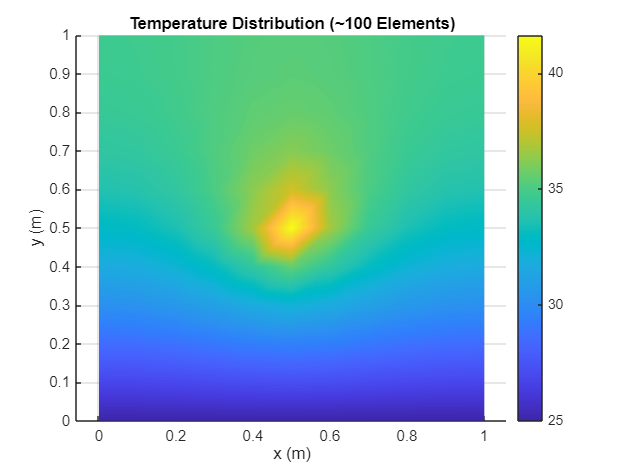


% Plot: temperature contour
figure;
trisurf(elements, nodes(:,1), nodes(:,2), T, 'FaceColor','interp');
colorbar;
title('Temperature Distribution (~100 Elements)');
xlabel('x (m)'); ylabel('y (m)'); zlabel('Temperature (°C)');
view(2); axis equal; shading interp;

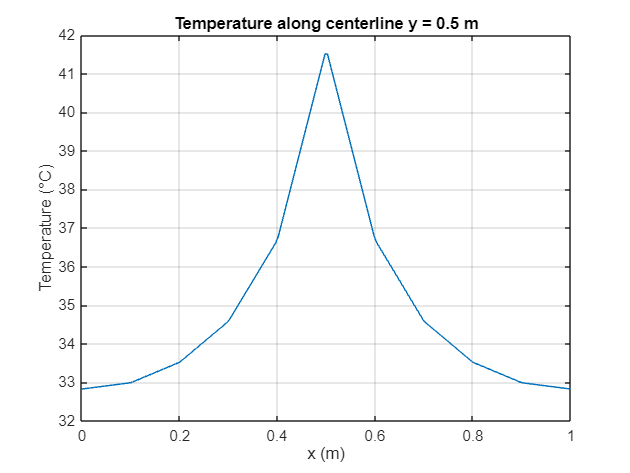


% Plot temperature along centerline (y = 0.5)
x_line = linspace(0, 1, 200);
T_line = griddata(nodes(:,1), nodes(:,2), T, x_line, 0.5 * ones(size(x_line)));

figure;
plot(x_line, T_line, '-');
title('Temperature along centerline y = 0.5 m');
xlabel('x (m)'); ylabel('Temperature (°C)');
grid on;